clear all;
clc;

## Loading data

addpath("data");
collect_time_table;

## Initial visualization

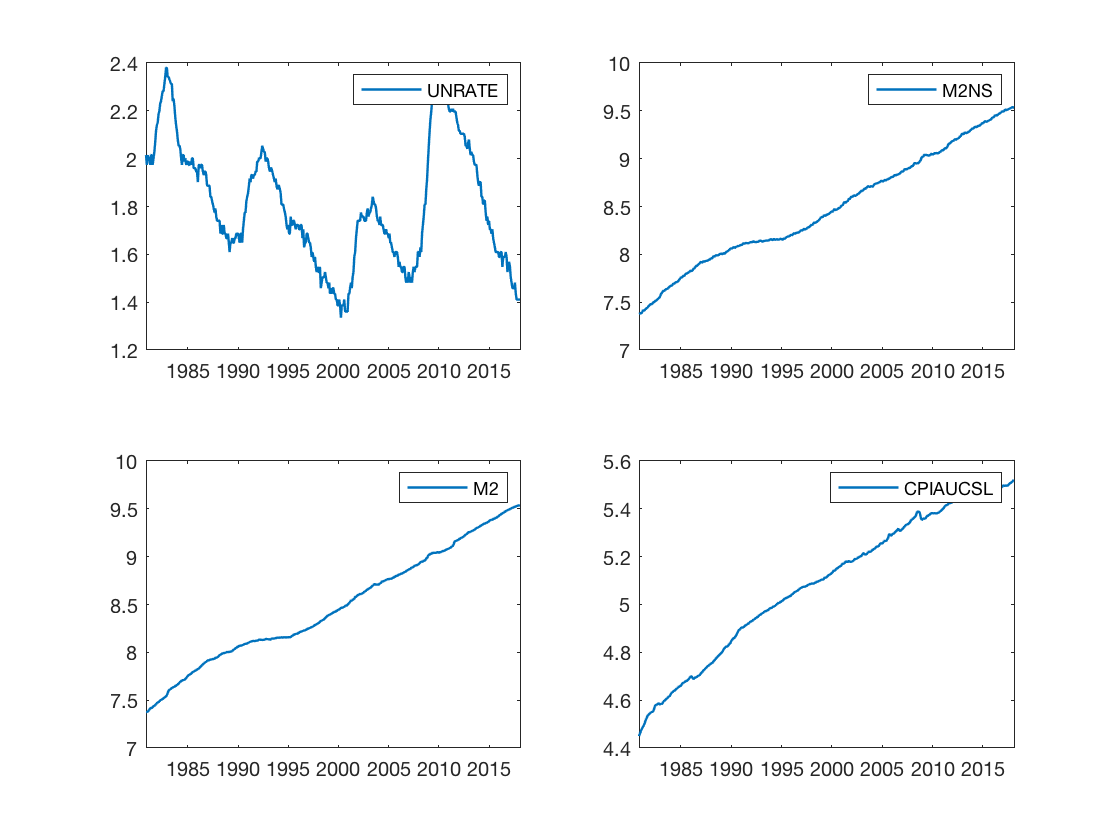

num_plot = length(names);
plot_size = ceil(sqrt(num_plot));
for i = 1:num_plot
    subplot(plot_size, plot_size, i);
    plot(data_tt.DATE, log(data_ar(:, i)), 'LineWidth', 1.2);
    legend(names{i});
end

## Creating data sets

numTimeStepsTrain = floor(0.7 * heigth(tt));

Undefined variable "data" or class "data.len".


XTrain = data.stack(:, 1: numTimeStepsTrain);
YTrain = data.main(:, 2: numTimeStepsTrain + 1);

XTest = data.stack(:, numTimeStepsTrain + 1: end - 1);
YTest = data.main(:, numTimeStepsTrain + 2: end);

## Standardize data (Mean Normalization)

mu = mean(XTrain')';
sig = std(XTrain')';

XTrain = (XTrain - mu) ./ sig;
YTrain = (YTrain - mu(1)) ./ sig(1);

XTest = (XTest - mu) ./ sig;

## Setup neural network

inputSize = 3;
numResponses = 1;

numHiddenUnits.lstm1 = 64;
numHiddenUnits.lstm2 = 32;
numHiddenUnits.fc1 = 64;
numHiddenUnits.fc2 = 32;

layers = [...
	sequenceInputLayer(inputSize, "Name", "Input layer")
	lstmLayer(numHiddenUnits.lstm1, "Name", "LSTM layer 1")
	lstmLayer(numHiddenUnits.lstm2, "Name", "LSTM layer 2")
	fullyConnectedLayer(numHiddenUnits.fc1, "Name", "FC layer 1")
	fullyConnectedLayer(numResponses, "Name", "Output layer")
	regressionLayer
	];

opts = trainingOptions(...
	"adam",...
	"MaxEpochs", 1500, ...
	"GradientThreshold", 10, ...
	"InitialLearnRate", 0.005, ...
	"LearnRateSchedule", "piecewise", ...
	"LearnRateDropPeriod", 250, ...
	"LearnRateDropFactor", 0.2, ...
    "MiniBatchSize", 48, ...
	"Verbose", 0, ...
	"Plot", "training-progress");

## Training

net = trainNetwork(...
	XTrain, ...
	YTrain, ...
	layers, ...
	opts);

## Predicting

net = predictAndUpdateState(net, XTrain);

YPred = [];

numTimeStepsTest = length(XTest);

% for i = 1:numTimeStepsTest
% 	[net, YPred(1, i)] = predictAndUpdateState(net, XTest(:, i));
% end

net = predictAndUpdateState(net, XTrain);

[net, YPred] = predictAndUpdateState(net, cache);

for i = 2:numTimeStepsTest
	[net, YPred(1, i)] = predictAndUpdateState(net, YPred(1, i-1));
end

% Unstandardize result
YPred = sig(1) * YPred + mu(1);

rmse = sqrt(mean(YPred - YTest) .^ 2);

YTrain = sig(1) * YTrain + mu(1);

## Visualize

figure
subplot(2, 1, 1)
plot(YTest, "-", "LineWidth", 1.25)
hold on
plot(YPred, "-", "LineWidth", 1.25)
grid on
hold off
legend(["Observed" "Predicted"])
ylabel("UNRATE(%)")
title("Civilian Unemployment Rate")

subplot(2, 1, 2)
stem(YPred - YTest)
xlabel("Month")
ylabel("Error")
title("RMSE = " + rmse)